# Custom solution validation

In some problems the solution provided by the solver may not be acceptable for some reasons.

In such cases, the solution validity can be checked using a custom solution validation function.

This exemple illustrate the validation of the solution in the case of a state constrained optimal control problem where the state constraint is tackled using an interior penalty (log-barrier). When the continuation procedure takes too large steps, it may happen that the solver fails to provide a numerical solution that lays in the interior of the admissible domain. As a result, complex state values may be obtained and other may exceed the limits. In that case it is necessary to indicate to the continuation procedure that the step has failed.

## Considered problem & method

### Original problem

The criterion to be minimized over $\left\lbrack 0,T\right\rbrack$, with $T=5s$, is :

$J=\int_0^T l\left(x\left(t\right),u\left(t\right)\right)\textrm{dt}$          (1)


$$l\left(x,u\right)=u^2$$


The system dynamics is : 

$\dot{x} \left(t\right)=f\left(x\left(t\right),u\left(t\right)\right)$              (2)

with $x\left(t\right)=\left\lbrack x_1 \left(t\right);x_2 \left(t\right)\right\rbrack$

$\frac{d{\mathrm{x}}_1 \left(t\right)}{\textrm{dt}}=x_2 \left(t\right)$                     (3)

$\frac{d{\mathrm{x}}_2 \left(t\right)}{\textrm{dt}}=u\left(t\right)-a\cdot {\sin \left({\mathrm{x}}_1 \left(t\right)\right)}^2$  (3)

The dynamic is 

The considered state constraint is 

$g\left(x\left(t\right)\right)<0$                                     (4)

with $g\left(x\left(t\right)\right)=x_2 \left(t\right)-\bar{x}$

The boundary condition is :

$x_1 \left(0\right)=0$;$x_1 \left(T\right)=D$                           (5)

$x_2 \left(0\right)=0$;$x_2 \left(T\right)=0$                           (6)

Numerical values : $D=4\pi$, $T=5$,  $a=0\ldotp 1$ .

Let us denote $p\left(t\right)=\left\lbrack p_1 \left(t\right);p_2 \left(t\right)\right\rbrack$ the co-state, the Hamiltonian associated with the problem is:

$H\left(x,u,p\right)=$$l\left(x\left(t\right),u\left(t\right)\right)+p^T \left(t\right)f\left(x\left(t\right),u\left(t\right)\right)$   (5)

### Penalization and regularization

A classical approach to deal with the state constaint (4) is to add a penalty into the criterion (1).

For instance, we may consider an interior penalty using log barier:

$J=\int_0^T \left\lbrack l\left(x\left(t\right),u\left(t\right)\right)+\sum_{i=1}^{n_g } \varphi \left(g_i \left(x\left(t\right)\right)\right)\right\rbrack \textrm{dt}$          (6)


$$\varphi \left(g\right)=-\varepsilon \ln \left(-\frac{g}{\sqrt{\varepsilon }}\right)$$
  

## Problem solving using continuation procedure

% Problem parameters
clearvars;close all; clc;
T=5;D=5*pi;epsi=10;a=0.1;xmax=10;finalXmax=4;

tStart=tic;

Choose here to use or not the custom validation

useCustomSolValidation=true;

### Initialization : solve without state constraint

We first try to solve the problem without state constraint .

paramStart={};paramStart.xmax=10;
fixedParams=createStructureFromVariable(D,a,epsi);

% Initialization of the BVP at steadystate
nInit=100;
solInit.x=linspace(0,T,nInit);
solInit.y=repmat([0;0;0;0],[1 nInit]);
bvpOpt=bvpset('RelTol',1e-2,'AbsTol',1e-4,"Nmax",30000);
problem=bvp4or5c('bvp5c',@generateFodeFcn,@generateBCFcn,bvpOptions=bvpOpt);

Try to solve

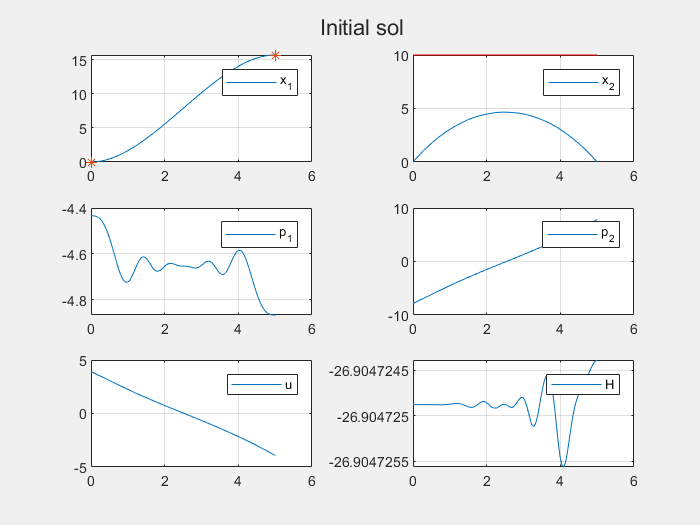

Problem solved


try        
    sol=problem.solveProblem(solInit,paramStart,fixedParams);
    sol=modifySolutionFcn(sol,true, paramStart,fixedParams);
    originalBVPsolved=true;

    % Display
    id=iterativeDisplay;
    id.newIteration;
    plotFigFcn([],0,id,sol,paramStart,fixedParams,"Initial sol");
    id.finalIteration;
    plotFigFcn([],0,id,sol,paramStart,fixedParams,"Initial sol");
    
    fprintf('Problem solved\n')
catch Error
    Error.message
    originalBVPsolved=false;
    fprintf('The problem was not solved using a standard bvp solver\n')
end

If the problem was not solved, then use initialization method to compute a solution

if ~originalBVPsolved
    Xss=[D/2;D/T];
    ocp=OCPsteadyStateInitialization(problem,Xss,T,'fixedParams',fixedParams,...
        'targetParams',paramStart,'nInit',1000,...
        "plotFigFcn",@plotFigFcn,...
        "modifySolutionFcn",@modifySolutionFcn);
    sol=ocp.run;
end

### Final State constraint 

We now decrease $\varepsilon$ downto a very small value

fixedParams=[];paramStart=[];paramEnd=[];
fixedParams.xmax=xmax;fixedParams.a=a;fixedParams.D=D;
fixedParams=createStructureFromVariable(D,a);
paramStart=createStructureFromVariable(epsi,xmax);
paramEnd.epsi=1e-2;paramEnd.xmax=finalXmax;
bvpOpt=bvpset('RelTol',1e-3,'AbsTol',1e-6,"Nmax",30000);

Here we decide to use or not the custom solution validation.

if useCustomSolValidation
    problem=bvp4or5c("bvp4c",@generateFodeFcn,@generateBCFcn,bvpOptions=bvpOpt,solValidationFcn=@solValidationFcn);
else
    problem=bvp4or5c("bvp4c",@generateFodeFcn,@generateBCFcn,bvpOptions=bvpOpt);
end
scheduler=logScheduler(paramStart,paramEnd, fixedParams=fixedParams,...
    initialDelta=0.5,beta=1.2,deltaMin=1e-6,lambdaMin=1e-8);

Checking initial solution feasability
Done (initial solution is feasible)
epsi&xmax - Iter : 002 Lambda : 4.1667e-01 delta : 4.17e-01
    epsi : 4.17e+00 - Xmax : 6.50e+00
epsi&xmax - Iter : 003 Lambda : 1.4468e-01 delta : 3.47e-01
    epsi : 1.46e+00 - Xmax : 4.87e+00
epsi&xmax - Iter : 004 Lambda : 4.1862e-02 delta : 2.89e-01
    epsi : 4.28e-01 - Xmax : 4.25e+00
 error validation
   => :Solution is discarded by the validation function 
epsi&xmax - Iter : 005 Lambda : 1.2754e-01 delta : 8.82e-01
    epsi : 1.28e+00 - Xmax : 4.77e+00
epsi&xmax - Iter : 006 Lambda : 9.3695e-02 delta : 7.35e-01
    epsi : 9.46e-01 - Xmax : 4.56e+00
epsi&xmax - Iter : 007 Lambda : 5.7360e-02 delta : 6.12e-01
    epsi : 5.83e-01 - Xmax : 4.34e+00
epsi&xmax - Iter : 008 Lambda : 2.9263e-02 delta : 5.10e-01
    epsi : 3.02e-01 - Xmax : 4.18e+00
 error validation
   => :Solution is discarded by the validation function 
epsi&xmax - Iter : 009 Lambda : 5.2677e-02 delta : 9.18e-01
    epsi : 5.36e-01 - Xmax : 4

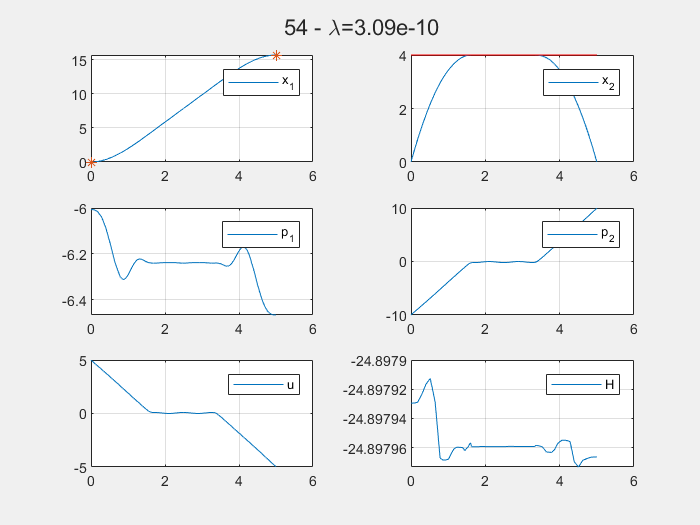

cont=continuationProcedure(problem,scheduler,sol,"plotFigFcn",@plotFigFcn,...
    "modifySolutionFcn",@modifySolutionFcn,'strIter','epsi&xmax',...
    "preIterPrintFcn",@preIterPrintFcnEpsiXmax);
cont.run;

sol=cont.sol;
fprintf('Duration : %.2f\n',toc(tStart))

Duration : 31.38


## Solution validation function

function isValid=solValidationFcn(sol,continuationParams,fixedParams)
% check if the provided solution complies with the constraint
retrieveContinuationParameters({continuationParams,fixedParams});
g=sol.y(2,:)-xmax;
isValid=all(g<=0 & isreal(sol.y));
if  ~isValid
    fprintf(" error validation\n")
end
end

## Functions related to the BVP to be solved

This code allows to compute the solution of the Hamiltonian minimization

function [u,H]=computeControlHamiltonian(x,p,epsi,a,xmax)
% Compute the optimal control u & v and the hamiltonian (if requested)
x1=x(1,:);x2=x(2,:);p1=p(1,:);p2=p(2,:);
u=-p2/2;
if nargout==2
    % Hamiltonian value is requested
    if epsi~=0
        H=p2.*u + p1.*x2 - epsi.*(log(xmax - x2) - log(epsi)./2) + u.^2 - a.*p2.*sin(x1).^2;
    else
        H=p1.*x2 + p2.*(u - a.*sin(x1).^2) + u.^2;
    end
end
end

The BVP dynamics is given here. It depends on several parameters  whose value wil be passed by the `generateFode` function.

function dydt=fdyn(y,epsi,a,xmax)
% Compute the BVP to be solved : dYdt=[dxdt;dpdt]
x=y(1:2,:);p=y(3:4,:);
x1=y(1,:);x2=y(2,:);p1=y(3,:);p2=y(4,:);
u=computeControlHamiltonian(x,p,epsi,a,xmax);
if epsi~=0
    % With penalty
    dxdt  = [  x2;
                u - a.*sin(x1).^2];
    dpdt  = [2.*a.*p2.*cos(x1).*sin(x1);
             epsi./(x2 - xmax) - p1];
else
    % No state penalty
    dxdt=[x2;u - a*sin(x1).^2 - x2.^2];
    dpdt=[2.*a.*p2.*cos(x1).*sin(x1);-p1];
end

dydt=[dxdt;dpdt];
end

This is the code for the boundary value problem.

function res=bcfun(ya,yb,D)
% Boundary condition to be canceled
res=[ya(1,1);
     yb(1,1)-D;
     ya(2,1)-0;
    yb(2,1)-0];
end

## Functions specific to the continuation procedure

- **generateFodeFcn**

`generateFodeFcn` has to provide a handle to the bvp dynamics according to the parameter values (manipulated or not by the continuation procedure). Here we use two continuation procedures. The first one does not modify rho, umin and umax whereas the other change them.

function fode=generateFodeFcn(continuationParams,fixedParams)
% retrieve a handle to the ode function with the current parameters
% values
retrieveContinuationParameters({continuationParams,fixedParams});
fode=@(t,y) fdyn(y,epsi,a,xmax);
end

- `generateBCFcn`

`generateBCFcn` has to provide a handle to the bvp boundary conditions according to the parameter values (manipulated or not by the continuation procedure). Here we use two continuation procedure. The first one does  modify `x0` and `xT` whereas the other does not change them.

function bcond=generateBCFcn(continuationParams,fixedParams)
% retrieve a handle to the boundary condition function with the
% current parameters values
retrieveContinuationParameters({continuationParams,fixedParams});
bcond=@(ya,yb) bcfun(ya,yb,D);
end

- `generateBVPoptionsFcn`

It is also possible to set the `bvpOptions` as continuation parameters. The `generateBVPoptionsFcn` function provide a `bvpOptions` structure based on the parameters of the continuation procedure.

function bvpOptions=generateBVPoptionsFcn(continuationParams,fixedParams)
retrieveContinuationParameters({continuationParams,fixedParams});
bvpOptions=bvpset('RelTol',relTol,'AbsTol',absTol,'Nmax',1e6);
end

- `modifySolutionFcn`

In the optimal control problem, the control $u_r$ and $u$ are computed but it remains an internal data usined internaly within the BVP dynamics `fdyn`. As we would like to display the controls signal, we need to add it to the solution structure. We also compute the Hamiltonian value in the same way. 

function sol=modifySolutionFcn(sol,iterSuccess,continuationParams,fixedParams)
if iterSuccess
    retrieveContinuationParameters({continuationParams,fixedParams});
    x=sol.y(1:2,:);p=sol.y(3:4,:);
    % Add the control signal u to the solution
    [sol.u,sol.H]=computeControlHamiltonian(x,p,epsi,a,xmax);
end
end

`preIterPrintFcnEpsi`

This function is used to print the current values of `epsi `during the continuation procedure.


function preIterPrintFcnEpsiXmax(algorithmState, continuationParams, fixedParams)
% This function is called before any iteration
retrieveContinuationParameters({continuationParams,fixedParams});
fprintf('%s - %s\n',algorithmState.strIter,algorithmState.schedulerStateStr);
fprintf('    epsi : %.2e - Xmax : %.2e\n',epsi,xmax);
end

- `plotFigFcn`

The `plotFigFcn` receive an `iterartiveDisplay` object that allows quick update of the graphics. It is advised to use it. The continuation procedure will call the `id.newIteration` and the `id.finalIteration` methods.

Alternatively, you may use your own code. The `plotFigFcn` function is called after every iteration of the continuation procedure with `status=2`. It is also called once before starting the continuation procedure with` status=1` in order to setup the figure layout and the handle to the different curves. At the end of the continuation procedure, it is called with `status=3` to perform the final update (in general to display the legends).

function dataPlot=plotFigFcn(dataPlot,status,id,sol,continuationParams,fixedParams,str)
% Display sol
retrieveContinuationParameters({continuationParams,fixedParams});

hFig=id.figure;
id.setOnce(hFig,'visible','on'); % Undock the figure

% Pepare a tiledlayout
h=id.tiledlayout('flow');


% Add a title with lambda value & iteration
h.Title.String=str;

for i=1:size(sol.y,1)/2
id.nexttile;
id.plot(sol.x,sol.y(i,:))
id.hold('on')
if i==1
id.plot(sol.x([1 end]),[0 D],'*');
end
if i==2
id.plot(sol.x([1 end]),[0 0]+xmax,'r');
end
id.grid('on');
id.legend(sprintf('x_%i',i));
end

m=size(sol.y,1)/2;
for i=1:size(sol.y,1)/2
id.nexttile;
id.plot(sol.x,sol.y(i+m,:))
id.hold('on');
id.grid('on');
id.legend(sprintf('p_%i',i));
end

id.nexttile;
id.plot(sol.x,sol.u)
id.grid('on');
id.legend('u')

id.nexttile;
id.plot(sol.x,sol.H)
id.grid('on');
id.legend('H')
drawnow;
end